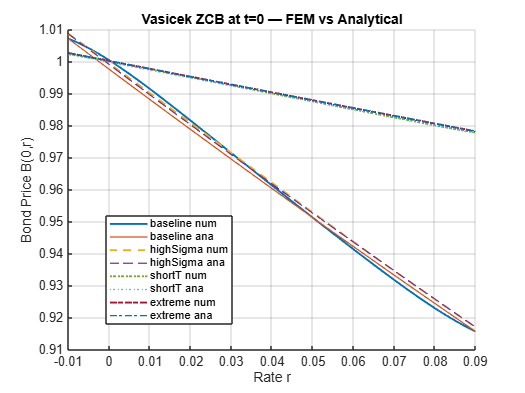

%% Vasicek ZCB via P1‐FEM + Crank–Nicolson — Multiple Test Scenarios + Plots
clear; clf;

%% 1) Common parameters & spatial mesh
a      = 0.1;      % mean‐reversion speed
b      = 0.05;     % long‐term mean
r_min  = -0.01;
r_max  =  0.09;
Ne     = 100;                           % number of elements
r      = linspace(r_min,r_max,Ne+1)';   % nodal coords
dr     = (r_max-r_min)/Ne;              % element size
Nnodes = Ne+1;                          % total nodes

% Preassemble mass matrix M (independent of sigma)
M = sparse(Nnodes,Nnodes);
for el = 1:Ne
    nodes = [el, el+1];
    h     = dr;
    Me    = (h/6) * [2,1;1,2];          % local mass
    M(nodes,nodes) = M(nodes,nodes) + Me;
end

%% 2) Define test scenarios
testCases = struct(...
  'name',  {'baseline','highSigma','shortT','extreme'},...
  'sigma', {0.02,       0.10,       0.02,     0.40   },...
  'T',     {1.00,       1.00,       0.25,     0.25   }...
);
nCases = numel(testCases);
L2err  = zeros(nCases,1);
H1err  = zeros(nCases,1);

% Preallocate containers for plotting bond curves
Bnum_mat = zeros(Nnodes,nCases);
Bex_mat  = zeros(Nnodes,nCases);

%% 3) Loop over each scenario
for k = 1:nCases
    sigma = testCases(k).sigma;
    T_k   = testCases(k).T;

    % Assemble stiffness matrix A for this sigma
    A = sparse(Nnodes,Nnodes);
    kappa = 0.5*sigma^2;
    for el = 1:Ne
        nodes   = [el, el+1];
        r_mid   = 0.5*(r(el)+r(el+1));
        alpha_e = a*(b - r_mid);
        beta_e  = r_mid + a;

        Ae_diff  = (kappa/dr) * [1,-1; -1,1];
        Ae_conv  = (alpha_e/2) * [1,1; -1,-1];
        Ae_react = beta_e*(dr/6)    * [2,1; 1,2];
        Ae       = Ae_diff + Ae_conv + Ae_react;

        A(nodes,nodes) = A(nodes,nodes) + Ae;
    end

    % Time‐stepping setup
    dt  = 0.005;
    Nt  = round(T_k/dt);
    Un  = ones(Nnodes,1);  % initial: B(τ=0)=1

    % Analytic helpers
    Btau_fun = @(t) (1 - exp(-a*(T_k - t))) / a;
    Atau_fun = @(t) ( Btau_fun(t) - (T_k - t) )*(b - sigma^2/(2*a^2)) ...
                   - (sigma^2 * Btau_fun(t)^2)/(4*a);

    % Crank–Nicolson loop
    for m = 1:Nt
        tau_m = m*dt;
        t_m   = T_k - tau_m;
        gL = exp( Atau_fun(t_m) - Btau_fun(t_m)*r_min );
        gR = exp( Atau_fun(t_m) - Btau_fun(t_m)*r_max );

        LHS =     M + 0.5*dt*A;
        RHS = ( M - 0.5*dt*A ) * Un;

        % Strong Dirichlet BCs
        LHS(1,:)    = 0; LHS(1,1)    = 1; RHS(1)    = gL;
        LHS(end,:)  = 0; LHS(end,end)= 1; RHS(end)  = gR;

        Un = LHS \ RHS;
    end

    % Numeric and exact at t=0
    B_num0      = Un;
    B_ex0       = exp( Atau_fun(0) - Btau_fun(0).*r );
    Bnum_mat(:,k) = B_num0;
    Bex_mat(:,k)  = B_ex0;

    % Compute errors
    L2err(k) = sqrt(trapz(r, (B_num0 - B_ex0).^2));
    d_num    = gradient(B_num0, dr);
    d_ex     = gradient(B_ex0,  dr);
    H1err(k) = sqrt(trapz(r, (d_num - d_ex).^2));
end

%% 4) Plot bond‐price curves for all scenarios
figure; hold on;
styles = {'-','--',':','-.'};
for k = 1:nCases
    plot(r, Bnum_mat(:,k), styles{k}, 'LineWidth',1.5, ...
         'DisplayName',[testCases(k).name ' num']);
    plot(r, Bex_mat(:,k),  styles{k}, 'LineWidth',1.0, ...
         'DisplayName',[testCases(k).name ' ana']);
end
xlabel('Rate r'); ylabel('Bond Price B(0,r)');
title('Vasicek ZCB at t=0 — FEM vs Analytical');
legend('Location','best'); grid on;

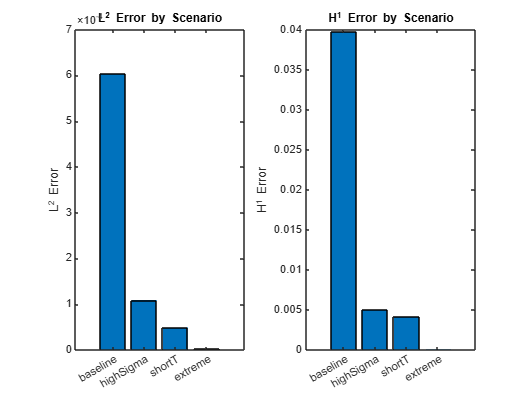


%% 5) Plot error bar charts
figure;
subplot(1,2,1);
bar(L2err);
set(gca,'XTick',1:nCases,'XTickLabel',{testCases.name});
ylabel('L^2 Error'); title('L^2 Error by Scenario');
subplot(1,2,2);
bar(H1err);
set(gca,'XTick',1:nCases,'XTickLabel',{testCases.name});
ylabel('H^1 Error'); title('H^1 Error by Scenario');


%% 6) Display error table
Scenario = {testCases.name}';
Sigma    = [testCases.sigma]';
Tmat     = [testCases.T]';
Results  = table(Scenario, Sigma, Tmat, L2err, H1err, ...
                  'VariableNames',{'Scenario','Sigma','T','L2Error','H1Error'});
disp(Results);

      Scenario       Sigma     T       L2Error       H1Error  
    _____________    _____    ____    __________    __________

    {'baseline' }    0.02        1    0.00060366       0.03978
    {'highSigma'}     0.1        1    0.00010891     0.0050027
    {'shortT'   }    0.02     0.25    4.9263e-05     0.0041712
    {'extreme'  }     0.4     0.25    2.0217e-06    8.9244e-05

